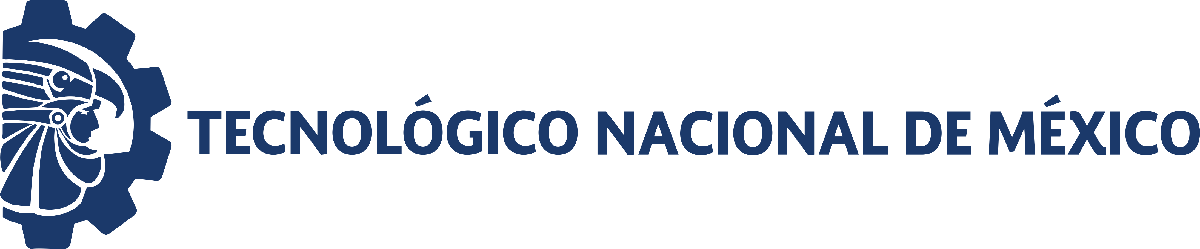                                 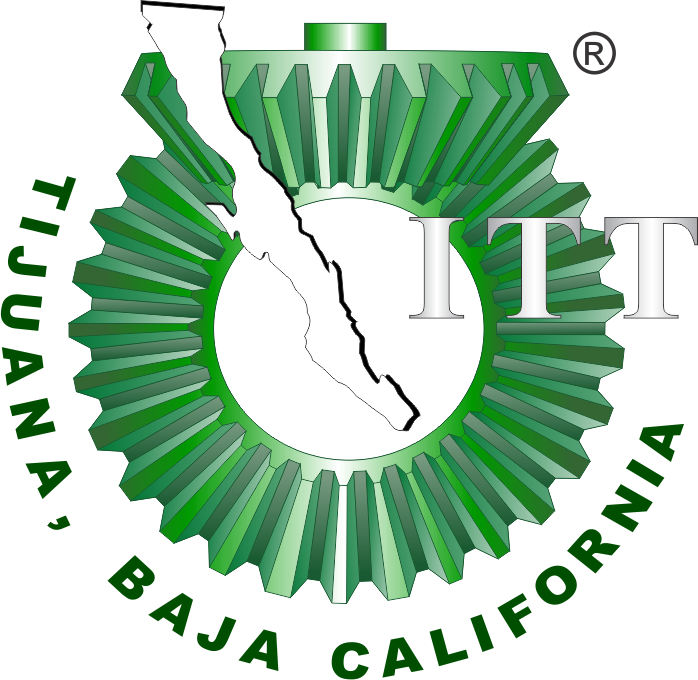

# Práctica 2: Sistema presa-depredador de Lotka-Volterra

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

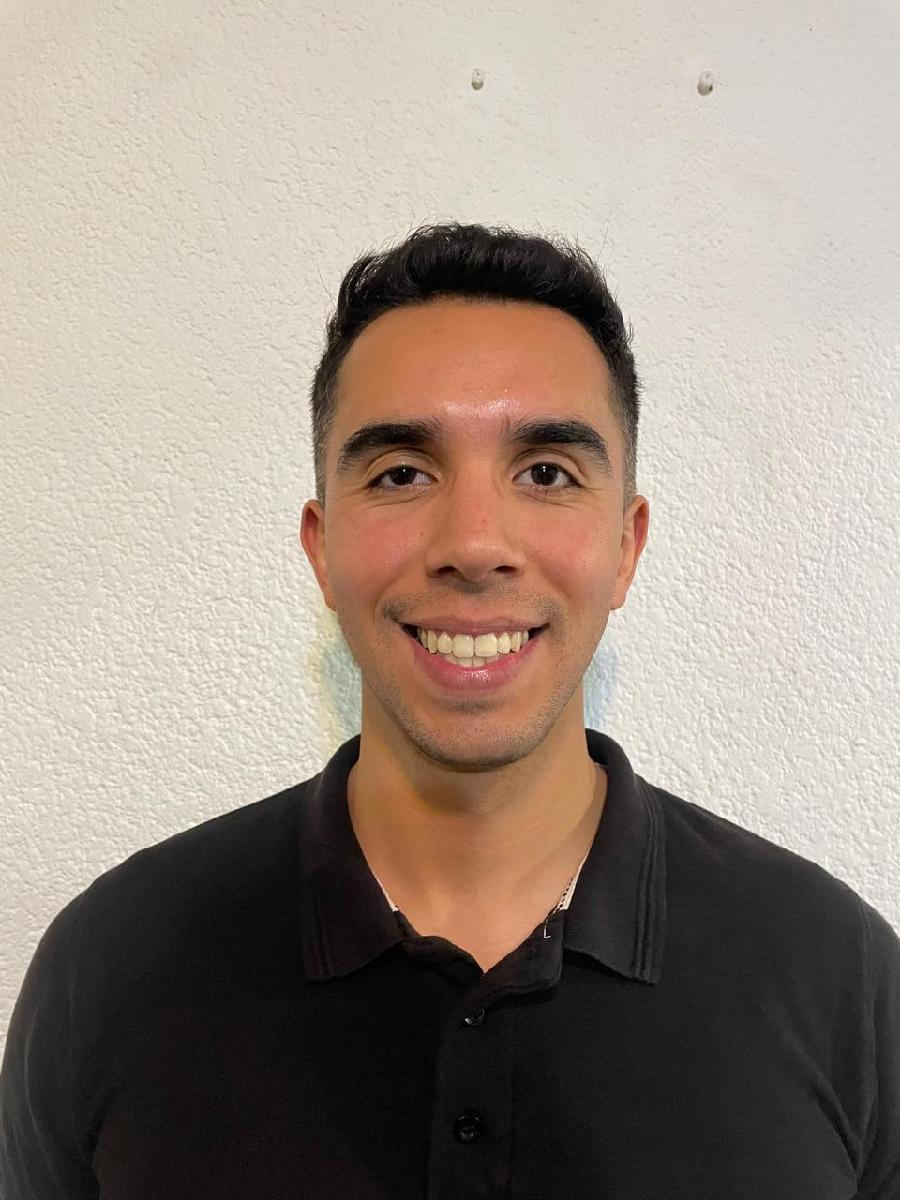

Nombre del alumno: **Carlos Andrés Gil Gárate**

Número de control: **21212743**

Correo institucional: **21212743@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo 

Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinámica en series de tiempo y el plano de fase. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$x=\alpha x-\beta \textrm{xy},$$



$$y=\delta \textrm{xy}-\gamma y,$$


con los valores de los parámetros $\alpha =0\ldotp 5$, $\beta =0\ldotp 01$, $\gamma =0\ldotp 2$, y las condiciones iniciales $x\left(0\right)=x_0 =75$ y  $y\left(0\right)=y_0 =75$.

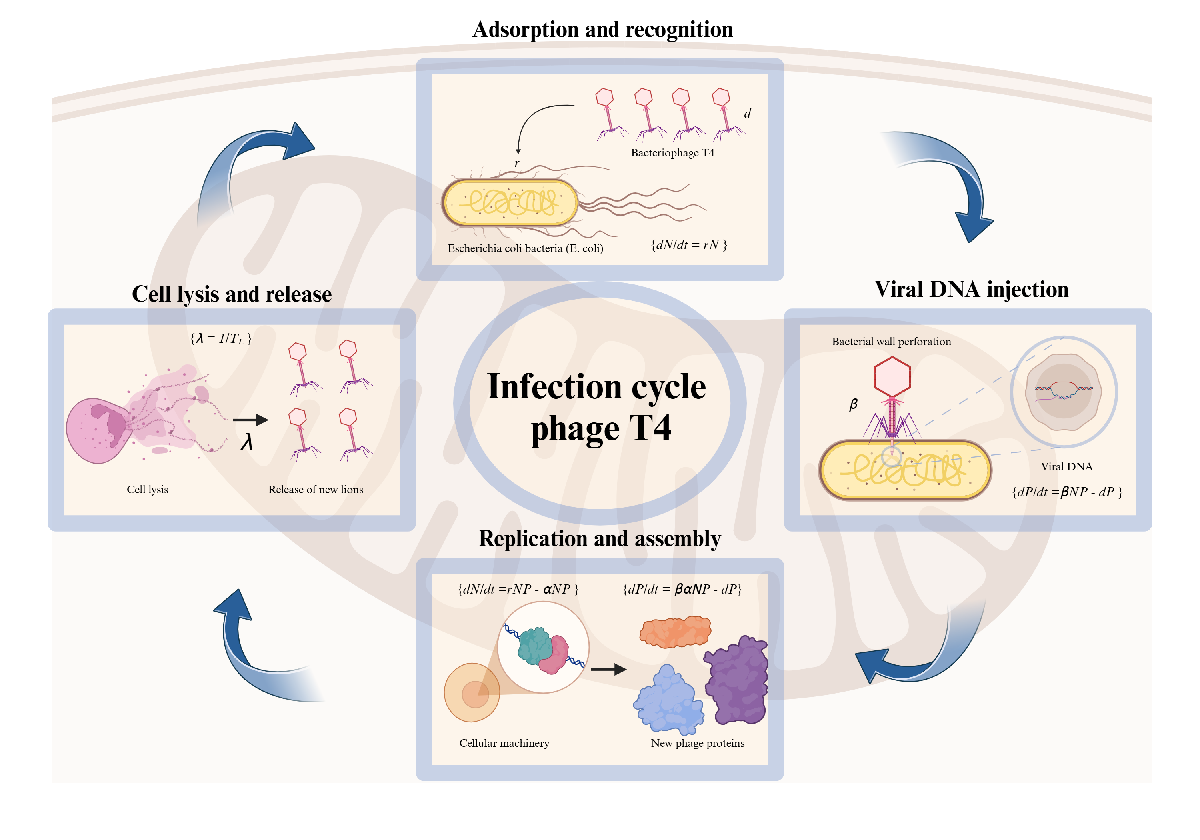

Figure. CAR-T cells [$y\left(t\right)$] encounter cancer cells [$x\left(t\right)$], these encounters result in both the eradication [negative feedback] of malignant cells at a rate $\beta$, and the expansion [positive feedback] of effector cells at a rate $\delta$, Additionaly, CAR-T cells die [exponential decay] at a rate given by $\gamma$, and cancer cells grow [exponential growth] at a rate denoted by $\mu$.  

clc; clear; close all; warning('off','all');

## Parameters and initial conditions 

alpha = 0.5;   beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;

## Solution by Euler's Method 

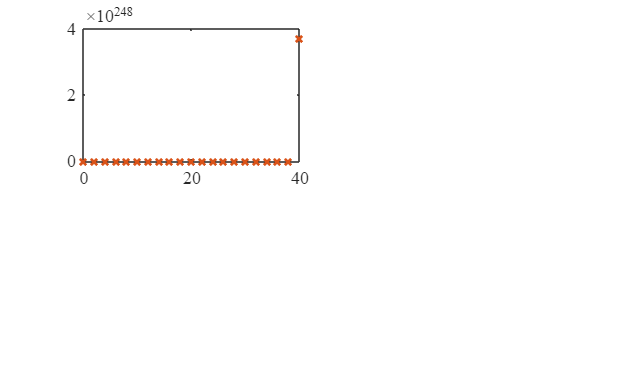

Index in position 2 exceeds array bounds. Index must not exceed 1.

Error in GD_GilGarateP2>plotEDOs (line 205)
    plot(t,x(:,2),'-','LineWidth',1,'Color',amr)

%dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4];
for i = 1:numel(dt)
    [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf,['Lotka-Volterra Euler', num2str(dt(i)),'.pdf'],'ContentType','Vector')
end 

### Solution by Heun's method

% % ----- Version Valle ----- %
%dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = 1E-1; 
for i = 1:numel(dt)
[t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
plotEDOs(t,x,y,P,dt(i))
exportgraphics(gcf,['Lotka-Volterra Euler', num2str(dt(i)),'.pdf'],'ContentType','Vector')
end 

### Simulink 

file = 'system';
sim(file);
parameters.StopTime = '100';

### Solution by ode15s [Stiff solver]

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode15s.pdf', 'ContentType', 'vector')

### Solution by ode23s [Stiff solver]

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode23s.pdf', 'ContentType', 'vector')

### Solution by ode23t [Stiff solver]

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode23t.pdf', 'ContentType', 'vector')

### Solution by ode23tb [stiff solver]

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode23tb.pdf', 'ContentType', 'vector')

## Solution by ode45 [Nonstiff solver]

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode45.pdf', 'ContentType', 'vector')

## Solution by ode23 [Nonstiff solver]

parameters.Solver = 'ode23';
s23 = sim(file,parameters);
plotEDOs(s23.t,s23.x,s23.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode23.pdf', 'ContentType', 'vector')

## Solution by ode1123[Nonstiff solver]

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode113.pdf', 'ContentType', 'vector')

### Conclusión

En base en las simulaciones numéricas y la literatura consultada, se concluye que este sistema no exhibe características de rigidez (*non-stiff*), lo que permite el uso de métodos de integración con pasos de tiempo más grandes sin comprometer la estabilidad y precisión de la solución. Este comportamiento es característico de los sistemas *non-stiff*, donde las soluciones varían de manera progresiva y no presentan cambios abruptos en escalas de tiempo reducidas. Dado que el sistema no es rígido, los métodos de integración explícitos convencionales, como *ode45*, *ode23* o *ode113*, resultan eficientes para su resolución, ya que no requieren pasos de integración excesivamente pequeños. Estos solucionadores permiten obtener resultados precisos con un menor costo computacional en comparación con los métodos implícitos utilizados en sistemas rígidos.

La clasificación del sistema como *non-stiff* depende de los valores de los parámetros del modelo, como las tasas de crecimiento y las interacciones entre especies. En este caso, las escalas de tiempo de la dinámica del sistema son comparables, lo que evita la aparición de rigidez y facilita la simulación con métodos de integración estándar.

#### Referencia 

- **M. A. Abbasi,** “Fixed points stability, bifurcation analysis, and chaos control of a Lotka–Volterra model with two predators and their prey,” *Int. J. Biomathematics*, vol. 17, no. 4, p. 2450017, 2024.

- **E. A. McGehee, N. Schutt, D. A. Vasquez, and E. Peacock-López,** “Bifurcations, and temporal and spatial patterns of a modified Lotka–Volterra model,” *Int. J. Bifurcation Chaos*, vol. 18, no. 8, pp. 2223–2248, 2008.

### Equilibrium points and Jacobian matrix

clc; clear; close all; warning('off','all')
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;

J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;

edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrium points.']);
X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
syms x0 y0 x1 y1
fprintf('Equilibrium points of the Lotka-Volterra system:'); 
disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1])
clear alpha beta delta gamma
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (', num2str(gamma/delta),',',num2str(alpha/beta),')'])

### Local stability

clc; clear; close all; warning('off','all')
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
syms x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0;x1]; y = [y0;y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)
L = zeros(length(x),length(x));
for i = 1:length(x)
    J = [alpha - beta*y(i),   -beta*x(i);
                 delta*y(i),  delta*x(i)-gamma]
    L(i,:) = eig(J);
end
L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

### Conclusión

El sistema presenta un estado estable porque presenta un caso marginal. Cumpliendo las condiciones de su centro; donde los valores propios son imaginarios y, a su vez, donde uno de los puntos de equilibrio son de orden superior y no aislados, correspondiendo al valor $R_e \lambda_0 =0$. 

### Equilibrium Points 

alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75;    y0 = 75;    tend = 100; 
dt = 1E-2;
[t,x,y] = sys_Heun(x0,y0,dt,tend,P);
plotEDOs(t,x,y,P,dt); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Lotka-Volterra Equilibria.pdf','ContentType','Vector')

## Data Filling 

clc; clear; close all; warning ('off','all')

### Raw Data

sys = readmatrix('data.xlsx');
to = round(sys(:,1)); xo = sys(:,2); yo = sys(:,3);
% T = array2table([t,x,y], 'VariableNames',{'t','x','y'}); disp(T)
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOs_fit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra.pdf','ContentType','vector')

### Smooth Data

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOs_fit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra (Smooth).pdf','ContentType','vector')

### Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);
fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra (Fit).pdf','ContentType','vector')

## Experimental Data for Population dynamics models in Ecology

### Data Filling

clc; clear; close all; warning ('off','all')

### Raw Data

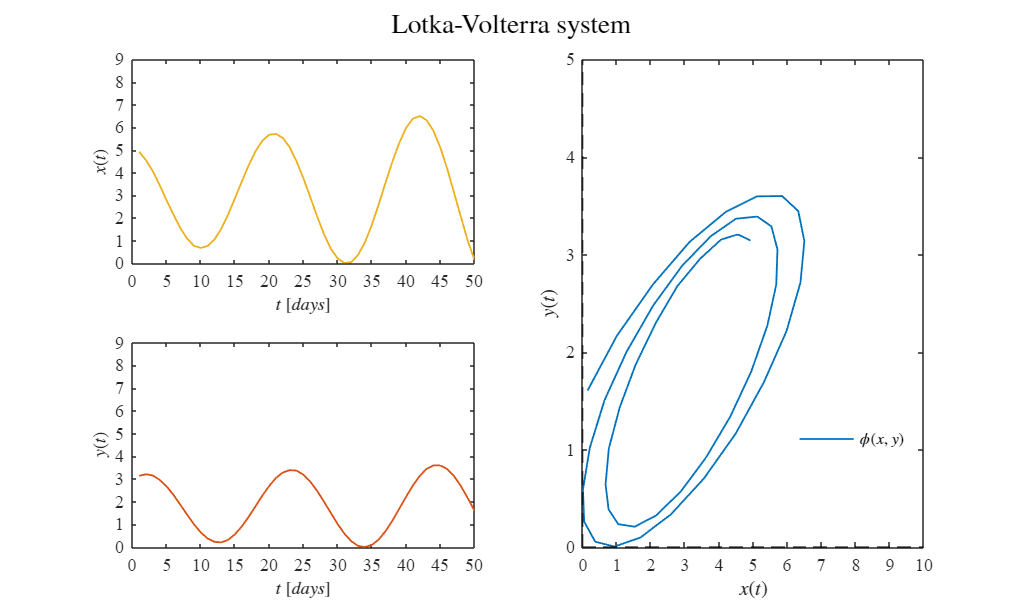

sys = readmatrix('data3.xlsx');
to = round(sys(:,1)); xo = sys(:,2); yo = sys(:,3);
% T = array2table([t,x,y], 'VariableNames',{'t','x','y'}); disp(T)
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];

plotProyect(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Datta Fitting Lotka-Volterra Proyecto.pdf','ContentType','vector') 

### Smooth Data

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
P0 = [0.9, 0.08, 0.011, 1.6];
% P0 = [0.9, 0.08, 0.011, 1.6]; -- Ultimo valor chido
% P0 = [0.4, 0.01, 0.09, 1.1]; % Valores cercanos a la tabla
   % Ajuste inicial
mdl = variant(to,xo,yo,P0);

t-Studen value: 1.985
 

Sample size (n): 50
Parameters to be estimated (pars): 4
Degrees of freedom: 96
Significance level (alpha): 0.05
-Student value: 1.9850
Adjusted R-squared: 0.8045
Corrected AIC (n/pars<40) : 229.9487
    Parameters    Estimate       SE         MoE               CI95              Pvalue  
    __________    ________    ________    ________    ____________________    __________

      alpha        0.32225    0.042802    0.084962     0.23729     0.40722    2.7833e-11
      beta         0.16798     0.01743    0.034598     0.13338     0.20258    8.9398e-16
      delta       0.085068    0.011721    0.023266    0.061801     0.10833    1.0214e-10
      gamma         0.2676    0.036779    0.073006     0.19459     0.34061    9.3609e-11



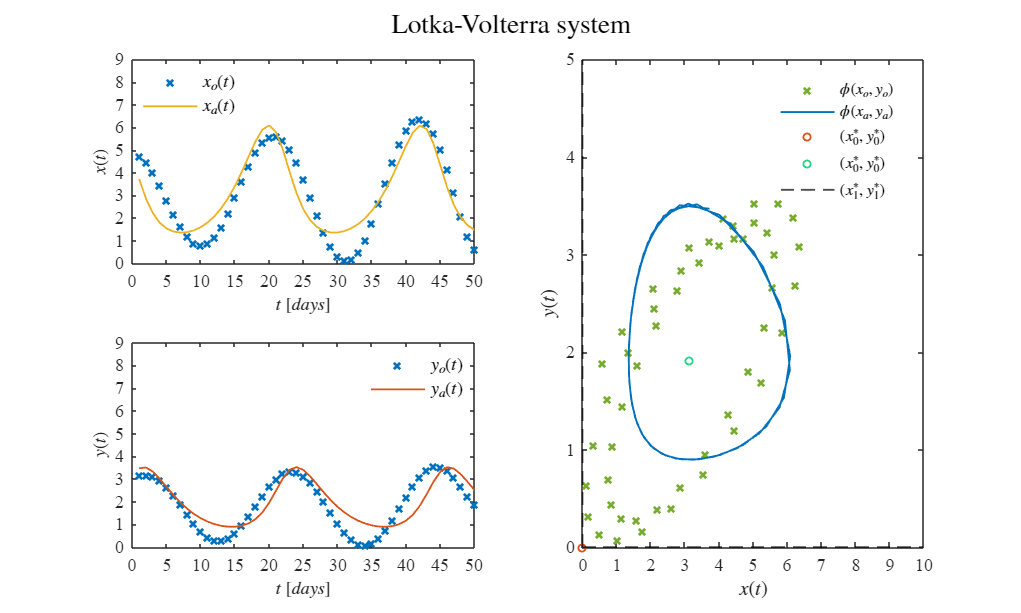

fa = mdl.Fitted;
fx= reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')

exportgraphics(gcf,'Lotka-Volterra(fitted).pdf','ContentType','vector')

Error using exportgraphics
The value of 'destination' is invalid. Unable to create output file 'Lotka-Volterra(fitted).pdf', Permission denied.

## Functions

### Euler's method 

function [t,x,y] = sys_Euler(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i) + (alpha*x(i) - beta*x(i)*y(i))*dt;
        y(i+1) = y(i) + (delta*x(i)*y(i) - gamma*y(i))*dt; 
    end 
end 

### Heun's Method 

function [t, x, y] = sys_Heun(x0, y0, dt, tend, P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend / dt);
    t = (0:dt:tend)'; 
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i =1: n
        [fx,fy] = f(x(i),y(i));

        xn = x(i) +fx*dt;
        yn = y(i) +fy*dt;
        [fxn,fyn] = f(xn,yn);

        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end

    function [dx,dy] = f(x,y)
        dx = alpha*x -beta*x*y;
        dy = delta*x*y -gamma*y;
    end
end

### Solutions and Trajectories 

    function plotEDOs(t,x,y,P,dt)
    % Colores a utilizar 
    blu = [0 0.4470 0.7410];
    nrj = [0.8500 0.3250 0.0980];
    amr = [0.9290 0.6940 0.1250];
    vrd = [0.4660 0.6740 0.1880];
    mor = [0.4940 0.1840 0.5560];
    naj = [0.8500 0.3250 0.0980];

    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',nrj)
    plot(t,x(:,2),'-','LineWidth',1,'Color',amr)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 50]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',amr)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',amr)
    plot(x(1),y(1),'o','MarkerSize',4,'LineWidth',1.5,'Color',[0, 0, 0]) % 1
    plot(0,0,'x','MarkerSize',5,'LineWidth',1.5,'Color',blu) % 2
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',1.5,'Color',mor) % 3
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$','$x^*_0,y^*_0$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$'); % 4
    % L = legend('$\phi(x,y)$'); % 5
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
    
    if dt == 0
        ttl = 'Lotka-Volterra System';
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
    end
end

function plotEDOs_fit(t,x,y,P,dt)
    % Colores a utilizar 
    blu = [0 0.4470 0.7410];
    nrj = [0.8500 0.3250 0.0980];
    amr = [0.9290 0.6940 0.1250];
    vrd = [0.4660 0.6740 0.1880];
    mor = [0.4940 0.1840 0.5560];
    naj = [0.8500 0.3250 0.0980];
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',amr)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',naj)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',blu)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
    
    if dt == 0
        ttl = 'Lotka-Volterra System';
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
    end
end

function plotProyect(t,x,y,P,dt)
    blu = [0 0.4470 0.7410];  % Azul
    nrj = [0.8500 0.3250 0.0980];  % Naranja
    amr = [0.9290 0.6940 0.1250];  % Amarillo
    vrd = [0.4660 0.6740 0.1880];  % Verde
    mor = [0.4940 0.1840 0.5560];  % Morado
    naj = [0.8500 0.3250 0.0980];  % Naranja (repetido)

    % Creación de la figura con fondo blanco y tamaño específico en centímetros
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])

    % Extraer los parámetros del sistema Lotka-Volterra
    alpha = P(1); 
    beta = P(2); 
    delta = P(3); 
    gamma = P(4);

    % Primera subgráfica: Evolución de x(t) en el tiempo
    subplot(2,2,1)
    set(gca, 'FontName', 'Times New Roman'); 
    fontsize(10, 'points');  % Se establece el tamaño de fuente
    hold on; box on; grid off;  % Configuración de la gráfica
    plot(t, x, '-', 'LineWidth', 1, 'Color', amr)  % Graficar x vs t
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex')  % Etiqueta en eje x
    ylabel('$x(t)$', 'Interpreter', 'Latex')  % Etiqueta en eje y
    xlim([0 50]); xticks(0:5:50)
    ylim([0 9]); yticks(0:1:9)


    % Segunda subgráfica: Evolución de y(t) en el tiempo
    subplot(2,2,3)
    set(gca, 'FontName', 'Times New Roman'); 
    fontsize(10, 'points');
    hold on; box on; grid off;
    plot(t, y, '-', 'LineWidth', 1, 'Color', naj)  % Graficar y vs t
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex')
    ylabel('$y(t)$', 'Interpreter', 'Latex')
    xlim([0 50]); xticks(0:5:50)
    ylim([0 9]); yticks(0:1:9)

    % Tercera subgráfica: Espacio de fase (x vs y)
    subplot(2,2,[2,4])
    set(gca, 'FontName', 'Times New Roman'); 
    fontsize(10, 'points');
    hold on; box on; grid off;
    plot(x, y, '-', 'LineWidth', 1, 'Color', blu)  % Graficar y vs x
    xlabel('$x(t)$', 'Interpreter', 'Latex')
    ylabel('$y(t)$', 'Interpreter', 'Latex')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 5]); yticks(0:1:5)

    % Añadir líneas de referencia en x=0 y y=0
    xline(0, '--', 'LineWidth', 1, 'Color', 'k') 
    yline(0, '--', 'LineWidth', 1, 'Color', 'k')

    % Leyenda
    L = legend('$\phi(x,y)$');
    set(L, 'Interpreter', 'Latex', 'Location', 'none', 'Position', [0.778,0.263,0.115,0.041], 'Box', 'Off')

    % Título de la figura
    if dt == 0
        ttl = 'Lotka-Volterra System';  % Nombre del sistema si no hay tamaño de paso
    else
        ttl = ['Step size: ', num2str(dt)];  % Indicar tamaño del paso si se ha especificado
    end
    sgtitle(ttl, 'Interpreter', 'Latex');  % Título general de la figura
end

function plotResults(t,x,y,P)
    blu = [0 0.4470 0.7410];  % Azul
    nrj = [0.8500 0.3250 0.0980];  % Naranja
    amr = [0.9290 0.6940 0.1250];  % Amarillo
    vrd = [0.4660 0.6740 0.1880];  % Verde
    mor = [0.4940 0.1840 0.5560];  % Morado
    naj = [0.8500 0.3250 0.0980];  % Naranja (repetido)
        set(figure(),'Color','w')
        set(gcf,'Units','Centimeters','Position',[2,2,20,12])
        alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

        subplot(2,2,1)
        set(gca,'FontName','Times New Roman'); fontsize(10,'points');
        hold on; box on; grid off;
        plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',blu)
        plot(t,x(:,2),'-','LineWidth',1,'Color',amr)
        xlabel('$t$ $[days]$','Interpreter','Latex')
        ylabel('$x(t)$','Interpreter','Latex')
        L = legend('$x_o(t)$','$x_a(t)$');
        set(L,'Interpreter','Latex','Location','Best','Box','Off')
        xlim([0 50]); xticks(0:5:50)
        ylim([0 9]); yticks(0:1:9)
    
    
        subplot(2,2,3)
        set(gca,'FontName','Times New Roman'); fontsize(10,'points');
        hold on; box on; grid off;
        plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',blu)
        plot(t,y(:,2),'-','LineWidth',1,'Color',naj)
        xlabel('$t$ $[days]$','Interpreter','Latex')
        ylabel('$y(t)$','Interpreter','Latex')
        L = legend('$y_o(t)$','$y_a(t)$');
        set(L,'Interpreter','Latex','Location','Best','Box','Off')
        xlim([0 50]); xticks(0:5:50)
        ylim([0 9]); yticks(0:1:9)
    
    
     subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;     
       plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',vrd) 
       plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',blu) 
       plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',naj) 
       plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',[35 213 132]/255)
       xlabel('$x(t)$','Interpreter','latex')
       ylabel('$y(t)$','Interpreter','latex')
       xlim([0 10]); xticks(0:1:10)
       ylim([0 5]); yticks(0:1:5)
    
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    
    L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
end

### Nonlinear regression algorithm 

function mdl= variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy = delta*x*y-gamma*y;
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end

        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha=0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['t-Studen value: ',num2str(tval)])
    disp(' ')
    
    fprintf('\nSample size (n): %d', numel(xo))
    fprintf('\nParameters to be estimated (pars): %d', numel(P0))
    fprintf('\nDegrees of freedom: %d', dof)
    fprintf('\nSignificance level (alpha): %.2f', alpha)
    fprintf('\n-Student value: %.4f', tval)
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted)
    fprintf('\nCorrected AIC (n/pars<40) : %.4f\n', mdl.ModelCriterion.AICc)
    
    disp(Results)
end 